# Create an Unordered List By Appending a MATLAB® Array to  a Document

You can create an unordered list by appending a MATLAB® array directly to a document or document part. The `append` method of the `mlreportgen.dom.Document` object creates an `mlreportgen.dom.UnorderedList` object from the array and appends the object to the document or document part.

The MATLAB array that you append to a document or document part can be a 1-by-n numeric array, array of character vectors, categorical array, or cell array. Use a cell array to specify elements having different types and to specify an element as a  DOM object, such as an mlreportgen.dom.Text object.

 This example appends a cell array to a document. The cell array contains character vectors, a number, and an `mlreportgen.dom.Text` object.

import mlreportgen.dom.*;

d = Document('myListReport','html');

t = Text('third item');
append(d,{'first item',6,t,'fourth item'});

close(d);
rptview(d);

Here is the generated list.

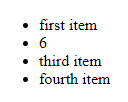

*Copyright 2019 The MathWorks, Inc.*